- **낙하산 병 예제**를 통해 Taylor 급수의 나머지 항을 계산에 적용하는 방법을 보여줍니다.

- Taylor 급수 전개:


$$v(t_{i+1}) = v(t_i) + v'(t_i)(t_{i+1} - t_i)$$


- 이 식을 통해 도함수 $v'(t_i)$를 근사화할 수 있습니다.

- 근사식: 


$$v'(t_i) = \frac{v(t_{i+1}) - v(t_i)}{t_{i+1} - t_i}$$


- 나머지 항을 고려한 근사:


$$v(t_{i+1}) = v(t_i) + v'(t_i)(t_{i+1} - t_i) + R_1$$


- $R_1$은 오차를 나타내며,$R_1 = \frac{v''(\xi)}{2!} (t_{i+1} - t_i)^2$로 표현됩니다.

- 이 오차는 $O(\Delta t)$로 표현될 수 있습니다.

- **절단 오차**:

- 도함수 근사값의 오차는 변수 간격의 크기에 비례함을 보여줍니다.

- 즉, 간격 $\Delta t$가 작아질수록 오차가 줄어듭니다.

% 초기 설정
t_i = 0; % 초기 시간
dt = 0.1; % 시간 간격
t_i1 = t_i + dt; % 다음 시간

% 예제 속도 함수 및 도함수
v = @(t) 5*t.^2 + 3*t + 2; % 예제 속도 함수
v_prime = @(t) 10*t + 3; % 실제 도함수
v_double_prime = @(t) 10; % 실제 이차 도함수

% t_i와 t_i+1에서의 속도 계산
v_ti = v(t_i);
v_ti1 = v(t_i1);

% 도함수 근사화
v_prime_approx = (v_ti1 - v_ti) / (t_i1 - t_i);

% 실제 도함수 값
v_prime_actual = v_prime(t_i);

% 오차 계산
error = v_prime_actual - v_prime_approx;

% 나머지 항을 통한 오차 추정
R1 = (v_double_prime(t_i) / 2) * (t_i1 - t_i);

% 결과 출력
fprintf('근사화된 도함수 값: %f\n', v_prime_approx);

근사화된 도함수 값: 3.500000


fprintf('실제 도함수 값: %f\n', v_prime_actual);

실제 도함수 값: 3.000000


fprintf('오차: %f\n', error);

오차: -0.500000


fprintf('나머지 항을 통한 오차 추정: %f\n', R1);

나머지 항을 통한 오차 추정: 0.500000


- 속도 함수 v(t)와 그 도함수 v'(t), 그리고 이차 도함수 v''(t)를 정의했습니다.

- $t_i$와$t_{i+1}$에서의 속도 값을 계산했습니다.

- 도함수의 근사값을 구하고, 실제 도함수 값과 비교하여 오차를 계산했습니다.

- Taylor 급수의 나머지 항을 이용하여 오차를 추정했습니다.

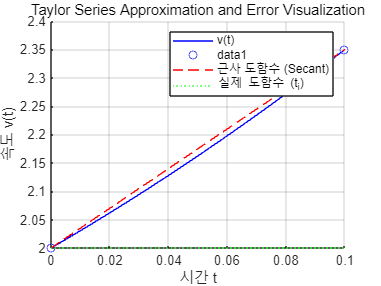

% 초기 설정
t_i = 0; % 초기 시간
dt = 0.1; % 시간 간격
t_i1 = t_i + dt; % 다음 시간

% 예제 속도 함수 및 도함수
v = @(t) 5*t.^2 + 3*t + 2; % 예제 속도 함수
v_prime = @(t) 10*t + 3; % 실제 도함수

% 시간 범위 설정
t_values = linspace(t_i, t_i1, 100);

% 속도 함수 및 실제 도함수 값 계산
v_values = v(t_values);
v_prime_actual = v_prime(t_i);

% 근사 도함수 값 계산
v_ti = v(t_i);
v_ti1 = v(t_i1);
v_prime_approx = (v_ti1 - v_ti) / (t_i1 - t_i);

% 시각화
figure;
hold on;

% 속도 함수 그래프
plot(t_values, v_values, 'b', 'DisplayName', 'v(t)');
scatter([t_i, t_i1], [v_ti, v_ti1], 'b');
plot([t_i, t_i1], [v_ti, v_ti1], 'r--', 'DisplayName', '근사 도함수 (Secant)');

% 실제 도함수 값 표시
yline(v_prime_actual * t_i + v_ti, 'g:', 'DisplayName', '실제 도함수 (t_i)');

% 레이블 및 제목
title('Taylor Series Approximation and Error Visualization');
xlabel('시간 t');
ylabel('속도 v(t)');
legend;
grid on;
hold off;

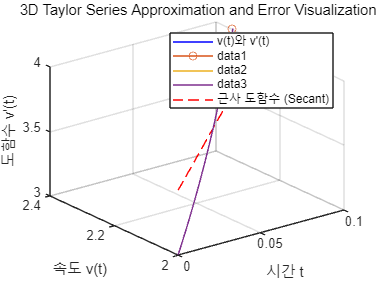

% 초기 설정
t_i = 0; % 초기 시간
dt = 0.1; % 시간 간격
t_i1 = t_i + dt; % 다음 시간

% 예제 속도 함수 및 도함수
v = @(t) 5*t.^2 + 3*t + 2; % 예제 속도 함수
v_prime = @(t) 10*t + 3; % 실제 도함수

% 시간 범위 설정
t_values = linspace(t_i, t_i1, 100);

% 속도 함수 및 실제 도함수 값 계산
v_values = v(t_values);
v_prime_values = v_prime(t_values);

% 근사 도함수 값 계산
v_ti = v(t_i);
v_ti1 = v(t_i1);
v_prime_approx = (v_ti1 - v_ti) / (t_i1 - t_i);

% 3D 시각화
figure;
hold on;

% 3D 속도 함수 그래프
plot3(t_values, v_values, v_prime_values, 'b', 'DisplayName', 'v(t)와 v''(t)');
comet3(t_values, v_values, v_prime_values); % 동적 표현

% 근사 도함수 그래프
plot3([t_i, t_i1], [v_ti, v_ti1], [v_prime_approx, v_prime_approx], 'r--', 'DisplayName', '근사 도함수 (Secant)');

% 레이블 및 제목
title('3D Taylor Series Approximation and Error Visualization');
xlabel('시간 t');
ylabel('속도 v(t)');
zlabel('도함수 v''(t)');
legend;
grid on;
view(3); % 3D 뷰 설정
hold off;

**1. 1차 도함수의 전진 차분 (First Forward Difference)**

- 식:$f'(x_i) = \frac{f(x_{i+1}) - f(x_i)}{h} + O(h)$

- 설명:

- 
$$h = x_{i+1} - x_i$$


- 작은 간격 h을 사용하여 현재 지점 $x_i$에서 다음 지점 $x_{i+1}$의 함수값 차이로 도함수를 근사화합니다.

- 전진 차분은 오차$O(h)$를 가집니다.

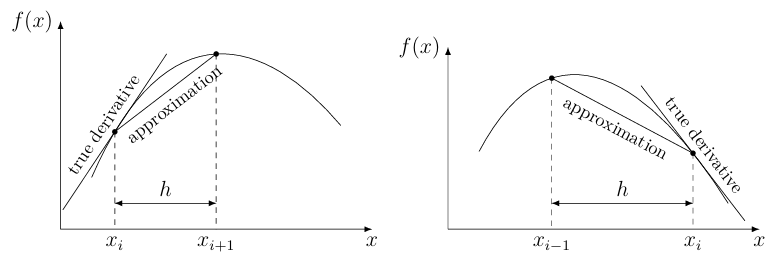

**2. 1차 도함수의 후진 차분 (First Backward Difference)**

- 식: $f'(x_i) = \frac{f(x_i) - f(x_{i-1})}{h} + O(h)$

- 설명:

- 
$$h = x_i - x_{i-1}$$


- 현재 지점 $x_i$에서 이전 지점$x_{i-1}$의 함수값 차이로 도함수를 근사화합니다.

- 후진 차분 또한 오차 O(h)를 가집니다.

**3. 1차 도함수의 중심 차분 (First Centered Difference)**

- 식: $f'(x_i) = \frac{f(x_{i+1}) - f(x_{i-1})}{2h} + O(h^2)$

- 설명:


$$h = x_{i+1} - x_i = x_i - x_{i-1}$$


- 이전 지점과 다음 지점의 함수값 차이의 평균으로 도함수를 근사화합니다.

- 중심 차분은 오차가$O(h^2)$로, 전진 및 후진 차분보다 더 정확한 근사값을 제공합니다.

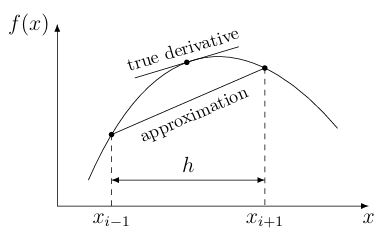

% 함수 및 구간 설정
f = @(x) -0.1*x.^4 - 0.15*x.^3 - 0.5*x.^2 - 0.25*x + 1.25; % 예제 함수
f_prime = @(x) -0.4*x.^3 - 0.45*x.^2 - 1.0*x - 0.25;  % 실제 도함수

x_i = 1; % 도함수를 계산할 지점
h = 0.1; % 간격

% 전진 차분
f_forward = (f(x_i + h) - f(x_i)) / h;

% 후진 차분
f_backward = (f(x_i) - f(x_i - h)) / h;

% 중심 차분
f_centered = (f(x_i + h) - f(x_i - h)) / (2*h);

% 실제 도함수 값
f_prime_actual = f_prime(x_i);

% 결과 출력
fprintf('전진 차분 근사값: %f\n', f_forward);

전진 차분 근사값: -2.260600


fprintf('후진 차분 근사값: %f\n', f_backward);

후진 차분 근사값: -1.950400


fprintf('중심 차분 근사값: %f\n', f_centered);

중심 차분 근사값: -2.105500


fprintf('실제 도함수 값: %f\n', f_prime_actual);

실제 도함수 값: -2.100000


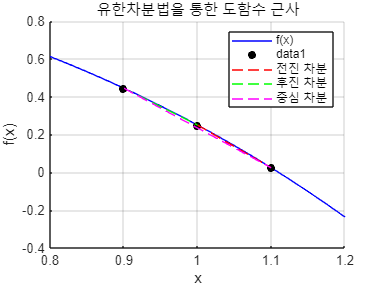


% 시각화
x_values = x_i-2*h:0.01:x_i+2*h;
f_values = f(x_values);

figure;
hold on;

% 함수 그래프
plot(x_values, f_values, 'b', 'DisplayName', 'f(x)');
scatter([x_i, x_i+h, x_i-h], [f(x_i), f(x_i+h), f(x_i-h)], 'k', 'filled');

% 전진 차분 선
plot([x_i, x_i+h], [f(x_i), f(x_i+h)], 'r--', 'DisplayName', '전진 차분');

% 후진 차분 선
plot([x_i-h, x_i], [f(x_i-h), f(x_i)], 'g--', 'DisplayName', '후진 차분');

% 중심 차분 선
plot([x_i-h, x_i+h], [f(x_i-h), f(x_i+h)], 'm--', 'DisplayName', '중심 차분');

% 레이블 및 제목
title('유한차분법을 통한 도함수 근사');
xlabel('x');
ylabel('f(x)');
legend;
grid on;
hold off;

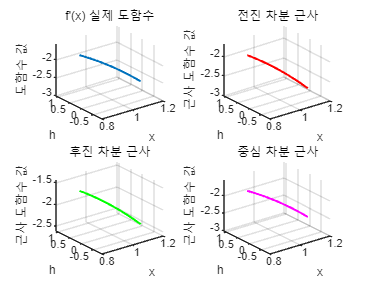

% 함수 및 구간 설정
f = @(x) -0.1*x.^4 - 0.15*x.^3 - 0.5*x.^2 - 0.25*x + 1.25; % 예제 함수
f_prime = @(x) -0.4*x.^3 - 0.45*x.^2 - 1.0*x - 0.25;  % 실제 도함수

x_i = 1; % 도함수를 계산할 지점
h = 0.1; % 간격

% x 범위 설정
x_values = x_i-2*h:0.01:x_i+2*h;

% 각 x_i에 대한 전진, 후진, 중심 차분 계산
F_forward = zeros(size(x_values));
F_backward = zeros(size(x_values));
F_centered = zeros(size(x_values));
F_actual = zeros(size(x_values));

for i = 1:length(x_values)
    xi = x_values(i);
    
    % 전진 차분
    F_forward(i) = (f(xi + h) - f(xi)) / h;
    
    % 후진 차분
    F_backward(i) = (f(xi) - f(xi - h)) / h;
    
    % 중심 차분
    F_centered(i) = (f(xi + h) - f(xi - h)) / (2 * h);
    
    % 실제 도함수 값
    F_actual(i) = f_prime(xi);
end

% 3D 시각화
figure;

% 실제 함수
subplot(2, 2, 1);
plot3(x_values, h * ones(size(x_values)), F_actual, 'LineWidth', 1.5);
title('f''(x) 실제 도함수');
xlabel('x');
ylabel('h');
zlabel('도함수 값');
grid on;

% 전진 차분
subplot(2, 2, 2);
plot3(x_values, h * ones(size(x_values)), F_forward, 'r', 'LineWidth', 1.5);
title('전진 차분 근사');
xlabel('x');
ylabel('h');
zlabel('근사 도함수 값');
grid on;

% 후진 차분
subplot(2, 2, 3);
plot3(x_values, h * ones(size(x_values)), F_backward, 'g', 'LineWidth', 1.5);
title('후진 차분 근사');
xlabel('x');
ylabel('h');
zlabel('근사 도함수 값');
grid on;

% 중심 차분
subplot(2, 2, 4);
plot3(x_values, h * ones(size(x_values)), F_centered, 'm', 'LineWidth', 1.5);
title('중심 차분 근사');
xlabel('x');
ylabel('h');
zlabel('근사 도함수 값');
grid on;

- **함수**:

- 
$$f(x) = -0.1x^4 - 0.15x^3 - 0.5x^2 - 0.25x + 1.25$$


- 실제 도함수 값 $f'(0.5) \approx -0.9125$

- **계산 조건**:

- $h = 0.5$와 $h = 0.25$일 때, 전진, 후진, 중심 차분을 사용하여$x = 0.5$에서 도함수 근사를 계산합니다.

- **전진 차분 근사**:

- 식: $f'(x_i) \approx \frac{f(x_{i+1}) - f(x_i)}{h}$

- $h = 0.5$: 근사값 $-1.45$, 오차 $58.9$

- $h = 0.25$: 근사값 $-1.1548$, 오차 $26.5$

- **후진 차분 근사**:

- 식: $f'(x_i) \approx \frac{f(x_i) - f(x_{i-1})}{h}$

- $h = 0.5$: 근사값 $-0.55$, 오차 $39.7$

- $h = 0.25$: 근사값 $-0.714$, 오차$21.7$

- **중심 차분 근사**:

- 식: $f'(x_i) \approx \frac{f(x_{i+1}) - f(x_{i-1})}{2h}$

- $h = 0.5$: 근사값 $-1.0$, 오차 $9.6$

- $h = 0.25$: 근사값 $-0.9344$, 오차$2.4$

- **결론**:

- 오차가 h의 크기에 따라 감소함을 보여줍니다.

- 중심 차분이 전진 및 후진 차분보다 더 작은 오차를 가짐을 확인할 수 있습니다.

% 함수 및 도함수 정의
f = @(x) -0.1*x.^4 - 0.15*x.^3 - 0.5*x.^2 - 0.25*x + 1.25;
f_prime_actual = -0.9125; % 실제 도함수 값

x_i = 0.5; % 도함수를 계산할 지점
h_values = [0.5, 0.25]; % 간격

% 결과 저장을 위한 배열
errors_forward = zeros(size(h_values));
errors_backward = zeros(size(h_values));
errors_centered = zeros(size(h_values));

% 계산 및 시각화
figure;
hold on;

for j = 1:length(h_values)
    h = h_values(j);
    
    % 전진 차분
    f_forward = (f(x_i + h) - f(x_i)) / h;
    errors_forward(j) = abs(f_prime_actual - f_forward) / abs(f_prime_actual) * 100;
    
    % 후진 차분
    f_backward = (f(x_i) - f(x_i - h)) / h;
    errors_backward(j) = abs(f_prime_actual - f_backward) / abs(f_prime_actual) * 100;
    
    % 중심 차분
    f_centered = (f(x_i + h) - f(x_i - h)) / (2 * h);
    errors_centered(j) = abs(f_prime_actual - f_centered) / abs(f_prime_actual) * 100;
end

fprintf('전진 차분 오차: %f\n', errors_forward);

전진 차분 오차: 58.904110
전진 차분 오차: 26.541096


fprintf('후진 차분 오차: %f\n', errors_backward);

후진 차분 오차: 39.726027
후진 차분 오차: 21.746575


fprintf('중심 차분 오차: %f\n', errors_centered);

중심 차분 오차: 9.589041
중심 차분 오차: 2.397260


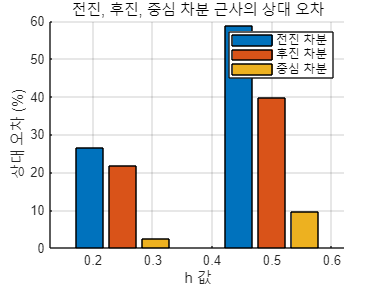



% 오차 결과 표시
bar(h_values, [errors_forward; errors_backward; errors_centered]', 'grouped');
title('전진, 후진, 중심 차분 근사의 상대 오차');
xlabel('h 값');
ylabel('상대 오차 (%)');
legend({'전진 차분', '후진 차분', '중심 차분'});
grid on;
hold off;

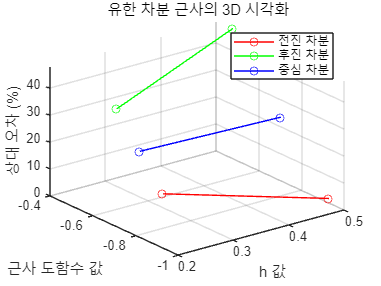

% 함수 및 도함수 정의
f = @(x) -0.1*x.^4 + 0.15*x.^3 - 0.5*x.^2 - 0.25*x + 1.25;
f_prime_actual = -0.9125; % 실제 도함수 값

x_i = 0.5; % 도함수를 계산할 지점
h_values = [0.5, 0.25]; % 간격

% 결과 저장을 위한 배열
f_forward_values = zeros(size(h_values));
f_backward_values = zeros(size(h_values));
f_centered_values = zeros(size(h_values));

% 계산
for j = 1:length(h_values)
    h = h_values(j);
    
    % 전진 차분
    f_forward = (f(x_i + h) - f(x_i)) / h;
    f_forward_values(j) = f_forward;
    
    % 후진 차분
    f_backward = (f(x_i) - f(x_i - h)) / h;
    f_backward_values(j) = f_backward;
    
    % 중심 차분
    f_centered = (f(x_i + h) - f(x_i - h)) / (2 * h);
    f_centered_values(j) = f_centered;
end

% 3D 시각화
figure;
hold on;

% 전진 차분 3D 그래프
plot3(h_values, f_forward_values, abs(f_prime_actual - f_forward_values) / abs(f_prime_actual) * 100, 'ro-', 'DisplayName', '전진 차분');

% 후진 차분 3D 그래프
plot3(h_values, f_backward_values, abs(f_prime_actual - f_backward_values) / abs(f_prime_actual) * 100, 'go-', 'DisplayName', '후진 차분');

% 중심 차분 3D 그래프
plot3(h_values, f_centered_values, abs(f_prime_actual - f_centered_values) / abs(f_prime_actual) * 100, 'bo-', 'DisplayName', '중심 차분');

% 레이블 및 제목
title('유한 차분 근사의 3D 시각화');
xlabel('h 값');
ylabel('근사 도함수 값');
zlabel('상대 오차 (%)');
legend;
grid on;
view(3);
hold off;

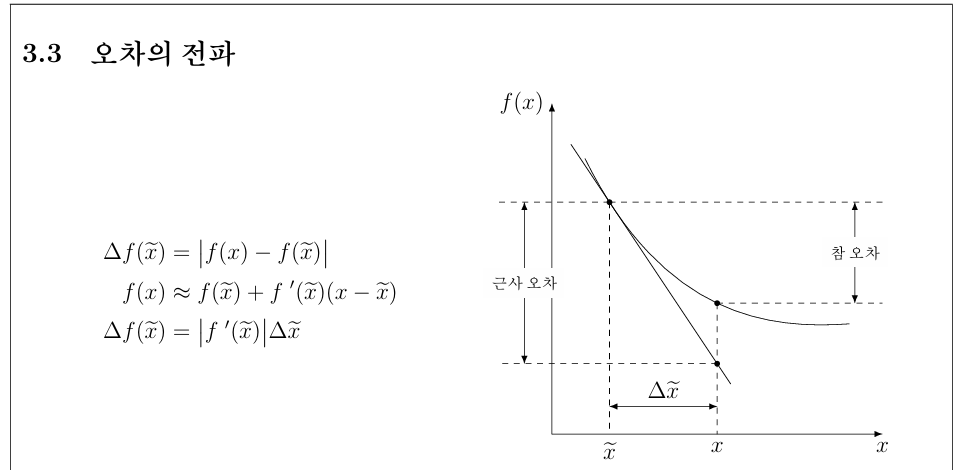

**1. 오차의 전파:**

- 함수 f(x)에서의 오차를 설명하고 있습니다.

- **오차의 전파**:


$$\Delta f(\bar{x}) = f'(\bar{x}) \Delta x$$


- 이 식은 f(x)의 변화가 x의 변화에 비례하여 선형적으로 변함을 나타냅니다.

- 예제:

$\bar{x} = 2.5$,$\Delta x = 0.01$일 때,

- $f'(x) = 3x^2$로 가정하고 계산:


$$\Delta f(\bar{x}) = 3(2.5^2) \times 0.01 = 0.1875$$



$$f(2.5) = 15.625$$


- 결과 범위: $15.4375 \leq f(x) \leq 15.8125$

**2. 함수의 상대오차:**

- 함수 f(x)의 상대오차를 정의합니다.

- 식: $f(xˉ)\frac{f(x) - f(\bar{x})}{f(\bar{x})} \approx \frac{f'(\bar{x}) \Delta x}{f(\bar{x})}f(xˉ)$ 

**3. 조건수 (Condition Number):**

- 조건수는 오차가 함수에 의해 증폭되는 정도를 나타냅니다.

- 식: $\frac{\bar{x}}{f(\bar{x})} f'(\bar{x})$

- 조건수가 클수록 함수의 안정성이 낮음을 의미합니다.

% 함수 및 도함수 정의
f = @(x) 3*x.^2; % 예제 함수
f_prime = @(x) 6*x; % 도함수

x_bar = 2.5; % 기준점
delta_x = 0.01; % 변화량

% 오차의 전파 계산
delta_f = f_prime(x_bar) * delta_x;

% 함수 값 계산
f_value = f(x_bar);
f_value_lower = f_value - delta_f;
f_value_upper = f_value + delta_f;

% 상대 오차 계산
relative_error = abs(delta_f / f_value);

% 조건수 계산
condition_number = (x_bar / f_value) * f_prime(x_bar);

% 결과 출력
fprintf('f(%.2f) = %.4f\n', x_bar, f_value);

f(2.50) = 18.7500


fprintf('오차의 전파 범위: [%.4f, %.4f]\n', f_value_lower, f_value_upper);

오차의 전파 범위: [18.6000, 18.9000]


fprintf('상대 오차: %.4f\n', relative_error);

상대 오차: 0.0080


fprintf('조건수: %.4f\n', condition_number);

조건수: 2.0000


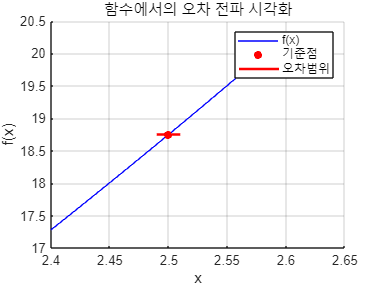


% 시각화
x_values = x_bar - 0.1:0.01:x_bar + 0.1;
f_values = f(x_values);

figure;
hold on;

% 함수 그래프
plot(x_values, f_values, 'b', 'DisplayName', 'f(x)');
scatter([x_bar], [f_value], 'r', 'filled');

% 가로 오차 막대 직접 그리기
line([x_bar - delta_x, x_bar + delta_x], [f_value, f_value], 'Color', 'r', 'LineWidth', 2);

% 레이블 및 제목
title('함수에서의 오차 전파 시각화');
xlabel('x');
ylabel('f(x)');
legend('f(x)','기준점','오차범위');
grid on;
hold off;

- **파란색 선**: 함수 f(x)의 그래프를 나타냅니다.

- **빨간색 점**: 기준점 x = 2.5에서의 함수 값 f(2.5)를 표시하고 있습니다.

- **빨간색 가로 오차 막대**: 이 막대는 기준점에서의 오차 범위를 보여줍니다. 이 오차는 $\Delta f(\bar{x}) = f'(\bar{x}) \Delta x$로 계산된 오차를 나타내며, 이를 통해 함수 값이 입력값의 변화에 따라 어떻게 변하는지 시각적으로 나타냅니다.

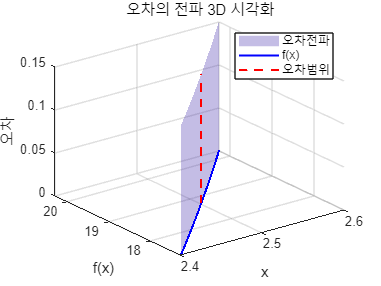

% 함수 및 도함수 정의
f = @(x) 3*x.^2; % 예제 함수
f_prime = @(x) 6*x; % 도함수

x_bar = 2.5; % 기준점
delta_x = 0.01; % 변화량

% x 범위 설정
x_values = x_bar - 0.1:0.01:x_bar + 0.1;

% 오차의 전파 계산
delta_f = f_prime(x_bar) * delta_x;

% 함수 값 및 오차 범위 계산
f_values = f(x_values);
f_value = f(x_bar);
f_value_lower = f_value - delta_f;
f_value_upper = f_value + delta_f;

% 3D 시각화
figure;
hold on;

% 3D 오차 평면
[X, Z] = meshgrid(x_values, [0, delta_f]);
Y = f(X);
surf(X, Y, Z, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% 실제 함수 값 선
plot3(x_values, f(x_values), zeros(size(x_values)), 'b', 'LineWidth', 1.5, 'DisplayName', 'f(x)');

% 기준점과 오차
plot3([x_bar, x_bar], [f_value, f_value], [0, delta_f], 'r--', 'LineWidth', 1.5, 'DisplayName', '오차 범위');

% 레이블 및 제목
title('오차의 전파 3D 시각화');
xlabel('x');
ylabel('f(x)');
zlabel('오차');
legend('오차전파','f(x)','오차범위');
grid on;
view(3);
hold off;

- **파란색 선**: f(x)함수의 값을 나타냅니다.

- **붉은색 점선**: 기준점에서의 오차 범위를 표시합니다.

- **반투명한 보라색 면**: 오차 전파를 시각적으로 보여주는 평면입니다.

**1. 수치 미분의 오차:**

- 중심 차분법을 사용하여 도함수 $f'(x_i)$를 구하는 식: 


$$f'(x_i) = \frac{f(x_{i+1}) - f(x_{i-1})}{2h} - \frac{f^{(3)}(\xi)}{6}h^2$$


- 여기서 오차는 두 가지로 나뉩니다:

- **절단 오차**: 미분을 근사할 때 발생하는 오차, 여기서는 $O(h^2)$에 해당합니다.

- **반올림 오차**: 유한한 자릿수로 인해 발생하는 오차.

**2. 오차 해석:**

- 유한 차분법에서는 반올림 오차와 절단 오차가 모두 포함됩니다.

- 간격 h가 작아질수록 반올림 오차는 증가하지만 절단 오차는 감소합니다.

**3. 예제:**

- 구간 간격을 $10^0$에서 $10^{-10}$까지 줄여가며 $f'(0.5)$를 구하는 과정이 나와 있습니다.

- 그래프는 구간 간격이 작아질 때 오차가 어떻게 변하는지 보여줍니다.

- x축: 구간 간격 h

- y축: 오차

- 구간 간격이 너무 작아지면 반올림 오차로 인해 오차가 다시 증가하는 현상을 보여줍니다.

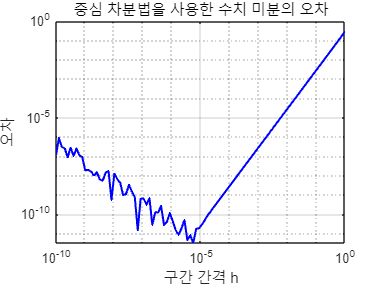

% 함수 및 도함수 정의
f = @(x) exp(x); % 예제 함수 (지수 함수)
f_prime_actual = @(x) exp(x); % 실제 도함수

x = 0.5; % 미분을 계산할 지점
h_values = logspace(0, -10, 100); % 구간 간격 h를 10^0에서 10^-10까지 로그 스케일로 설정

% 오차 계산
errors = zeros(size(h_values));
for i = 1:length(h_values)
    h = h_values(i);
    f_prime_approx = (f(x + h) - f(x - h)) / (2 * h); % 중심 차분법
    errors(i) = abs(f_prime_approx - f_prime_actual(x)); % 실제 도함수 값과 비교하여 오차 계산
end

% 시각화
figure;
loglog(h_values, errors, 'b-', 'LineWidth', 1.5);
title('중심 차분법을 사용한 수치 미분의 오차');
xlabel('구간 간격 h');
ylabel('오차');
grid on;

- 함수 $f(x) = e^x$와 실제 도함수 $xf'(x) = e^x$를 정의했습니다.

- 간격 h를 $10^0$에서 $10^{-10}$까지 로그 스케일로 설정했습니다.

- 각 h에 대해 중심 차분법을 사용하여 수치 미분을 계산하고 실제 도함수와의 오차를 구했습니다.

- `log` 함수를 사용하여 구간 간격과 오차의 관계를 로그-로그 스케일로 시각화했습니다.

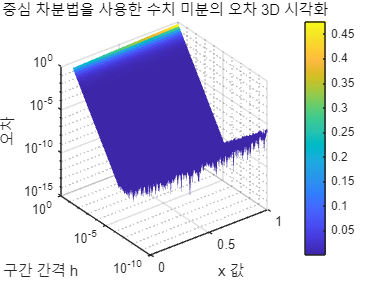

% 함수 및 도함수 정의
f = @(x) exp(x); % 예제 함수 (지수 함수)
f_prime_actual = @(x) exp(x); % 실제 도함수

x_values = linspace(0.1, 1, 100); % x 값의 범위 설정
h_values = logspace(0, -10, 100); % 구간 간격 h를 10^0에서 10^-10까지 로그 스케일로 설정

% 3D 오차 계산
[X, H] = meshgrid(x_values, h_values); % 그리드 생성
Errors = zeros(size(X));

for i = 1:length(h_values)
    for j = 1:length(x_values)
        h = h_values(i);
        x = x_values(j);
        f_prime_approx = (f(x + h) - f(x - h)) / (2 * h); % 중심 차분법
        Errors(i, j) = abs(f_prime_approx - f_prime_actual(x)); % 실제 도함수 값과 비교하여 오차 계산
    end
end

% 3D 시각화
figure;
surf(X, H, Errors, 'EdgeColor', 'none');
set(gca, 'ZScale', 'log', 'YScale', 'log'); % y축과 z축을 로그 스케일로 설정
title('중심 차분법을 사용한 수치 미분의 오차 3D 시각화');
xlabel('x 값');
ylabel('구간 간격 h');
zlabel('오차');
colorbar;
grid on;
view(3);

**그래프설명**

- **x축**: x 값의 범위 (0.1부터 1까지)

- **y축**: 구간 간격 h (로그 스케일로 표시)

- **z축 (오차)**: 오차의 크기 (로그 스케일로 표시)

- **색상 막대**: 오차의 크기를 색상으로 표현하여 시각적으로 구분합니다.

**구간 간격 h****의 영향**:

- h가 매우 작을 때 반올림 오차로 인해 오차가 증가하는 현상이 보입니다.

- 중간 영역에서 오차가 최소화되는 구간이 나타나며, 이때가 가장 정확한 수치 미분 결과를 제공합니다.

- h가 커지면 절단 오차가 증가하여 전체 오차가 커집니다.

**색상 변화**:

- 색상 막대를 통해 오차의 크기를 쉽게 비교할 수 있습니다.

- 오차가 클수록 색상이 밝게 표시되고, 오차가 작을수록 어둡게 표시됩니다.

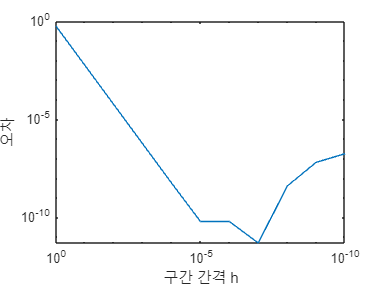

format long
x = 1;
n = 11;

func = @(x) -0.1*x^4 - 0.15*x^3 - 0.5*x^2 - 0.25*x + 1.2;
dfunc = @(x) -0.4*x^3 - 0.45*x^2 - x - 0.25;
dftrue = dfunc(x);

H = 10.^(-0:-1:-(n-1)); % 벡터의 길이가 n이 되도록 수정
D = zeros(1, n);
E = zeros(1, n);

for i = 1:n
    h = H(i); % 구간 간격
    D(i) = (func(x + h) - func(x - h)) / (2*h); % finite difference
    E(i) = abs(dftrue - D(i)); % 오차
end

%% Figure
figure1 = figure;
axes1 = axes('Parent', figure1);
loglog(H, E);
set(axes1, 'XDir', 'reverse'); % x축 반전
xlabel('구간 간격 h')
ylabel('오차')

**문제**

f(x)=cosx를 $x = \frac{\pi}{4}$에서의 값을 기준으로 $n = 0$부터$n = 4$까지 Taylor 급수로 $x = \frac{\pi}{3}$에서 근사

`taylor(f, var, a, 'Order', n)`: 함수 `f`에 대해 변수 `var`의 주변 a에서 n-1차까지의 Taylor 급수를 계산합니다.

% Symbolic Math Toolbox를 이용한 Taylor 급수 전개

% 심볼릭 변수 정의
syms x

% 함수 정의
f = cos(x);

% Taylor 급수 전개 (x = pi/4 주변에서 taylor 급수 5개항, 즉 4 차수까지)
taylor_expansion = taylor(f, x, pi/4, 'Order', 5);

% 결과 출력
disp('Taylor 급수 전개 (x = pi/4에서 n = 4 차수까지):');

Taylor 급수 전개 (x = pi/4에서 n = 4 차수까지):


disp(taylor_expansion);

$$\frac{\sqrt{2}}{2}-\frac{\sqrt{2}\,\left(x-\frac{\pi }{4}\right)}{2}-\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{2}}{4}+\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{3}}{12}+\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{4}}{48}$$


% 근사값 계산 (x = pi/3에서)
approx_value = double(subs(taylor_expansion, x, pi/3));
disp(['x = pi/3에서의 근사값: ', num2str(approx_value)]);

x = pi/3에서의 근사값: 0.50001



% 실제 값과 비교
actual_value = cos(pi/3);
disp(['x = pi/3에서의 실제 값: ', num2str(actual_value)]);

x = pi/3에서의 실제 값: 0.5


disp(['오차: ', num2str(abs(actual_value - approx_value))]);

오차: 7.5508e-06


Taylor 급수에서 잔여항 $R_n$을 정확히 측정하기 위해서는 일반적으로 실제 함수의 값이 필요합니다. 그러나 실제 값이 없을 때, 잔여항의 최대 크기를 추정하거나, $R_n$의 상한을 구하는 방법이 있습니다. 이는 주로 미분의 평균값 정리와 함수의 $(n+1)$차 미분을 이용하여 이론적으로 오차를 추정하는 방식입니다.

**1. 잔여항 **$R_n$**의 이론적 상한**

- Taylor 급수의 잔여항은 다음과 같이 표현될 수 있습니다:


$$R_n = \frac{f^{(n+1)}(\xi)}{(n+1)!} (x - a)^{n+1}$$


- 여기서 $\xi$는 a와 x 사이의 어떤 점이고, $f^{(n+1)}(\xi)$는 함수의 (n+1)차 미분입니다.

- 이 식을 통해 $R_n$의 최대값을 추정할 수 있습니다. 특히 $f^{(n+1)}(x)$의 최대값을 사용하면, 잔여항의 상한을 구할 수 있습니다.

**2. 오차 상한 추정 방법**

- **(****n****+****1****)****차 미분의 최대값 찾기**:

- 주어진 구간에서 $f^{(n+1)}(x)$의 최대값 M을 찾습니다.

- **오차 상한 계산**:

- 오차의 최대값은 다음과 같이 추정할 수 있습니다:


$$|R_n| \leq \frac{M}{(n+1)!} |x - a|^{n+1}$$


아래 코드는$f(x) = \cos x$에 대해 $n = 4$차 Taylor 급수의 잔여항의 상한을 추정하는 방법을 보여줍니다.

% 심볼릭 변수 및 함수 정의
syms x
f = cos(x);

% Taylor 급수의 중심점과 근사할 점
a = pi/4;
x_value = pi/3;

% (n+1)차 미분
n = 4;
f_n1 = diff(f, n+1);

% 구간에서의 (n+1)차 미분의 최대값 찾기
% x = a와 x = x_value 사이에서 f_n1의 최대값 추정
max_f_n1 = double(max(abs(subs(f_n1, x, linspace(a, x_value, 1000)))));

% 잔여항의 상한 계산
Rn_bound = (max_f_n1 / factorial(n+1)) * abs(x_value - a)^(n+1);

% 결과 출력
fprintf('잔여항의 상한 (n=4): %.6e\n', Rn_bound);

잔여항의 상한 (n=4): 8.875494e-06
